## Backtesting a set of tickers 

The objective of this notebook is to showcase how to backtest a portfolio consisting of a number of tickers and weights.

### Importing market data

Duplicate table variable name: 'Date'.

initDate = '1-Jan-2014';
symbol = 'AAPL';
aaplusd_yahoo_raw = getMarketDataViaYahoo(symbol, initDate);
aaplusd_yahoo = timeseries([aaplusd_yahoo_raw.Close, aaplusd_yahoo_raw.High, aaplusd_yahoo_raw.Low], datestr(aaplusd_yahoo_raw(:,1).Date));
aaplusd_yahoo.DataInfo.Units = 'USD';
aaplusd_yahoo.Name = symbol;
aaplusd_yahoo.TimeInfo.Format = "dd-mm-yyyy";
aaplusd_yahoo.plot()

### Construct and backtest a portfolio

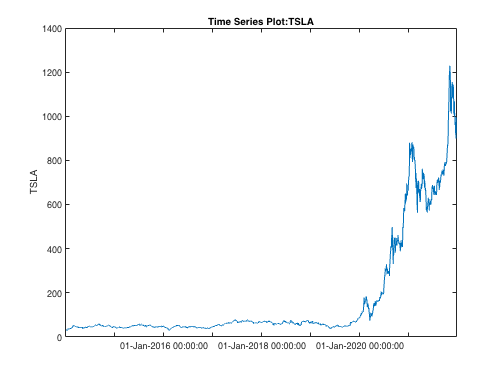

weight_apple = 0.5;
weight_tesla = 0.5;

history = getMarketDataViaYahoo('TSLA', initDate);
apple = getMarketDataViaYahoo('AAPL', initDate);

tsla_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', "TSLA");
apple_price = timeseries(apple.Close, datestr(apple(:,1).Date), 'Name', "AAPL");
tsla_price.plot()

TT = timeseries2timetable([tsla_price apple_price])

TT = 2009×2 timetable
       Time         TSLA      AAPL 
    ___________    ______    ______

    02-Jan-2014     30.02    19.755
    03-Jan-2014    29.912    19.321
    06-Jan-2014      29.4    19.426
    07-Jan-2014    29.872    19.287
    08-Jan-2014    30.256    19.409
    09-Jan-2014    29.506    19.161
    10-Jan-2014    29.144    19.034
    13-Jan-2014    27.868    19.133
    14-Jan-2014    32.254    19.514
    15-Jan-2014    32.826    19.906
    16-Jan-2014    34.194    19.795
    17-Jan-2014    34.002     19.31
    21-Jan-2014    35.336     19.61
    22-Jan-2014    35.712    19.697
    23-Jan-2014      36.3    19.864
    

TT.TSLA

ans = 	1.0e+03 *

    0.0300
    0.0299
    0.0294
    0.0299
    0.0303
    0.0295
    0.0291
    0.0279
    0.0323
    0.0328


## Dynamically read tickers from text file

fileID = fopen('tickers.txt','r');
initDate = '1-Jan-2014';
A = fscanf(fileID, "%s");
tickers = strsplit(A, ",");
results = {};
for tckr = tickers
    history = getMarketDataViaYahoo(tckr{1}, initDate);    
    history_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', tckr{1});
    results = [results history_price];
end
tt = timeseries2timetable(results);

tt = 2010×2 timetable
       Time         TSLA      AAPL 
    ___________    ______    ______

    02-Jan-2014     30.02    19.755
    03-Jan-2014    29.912    19.321
    06-Jan-2014      29.4    19.426
    07-Jan-2014    29.872    19.287
    08-Jan-2014    30.256    19.409
    09-Jan-2014    29.506    19.161
    10-Jan-2014    29.144    19.034
    13-Jan-2014    27.868    19.133
    14-Jan-2014    32.254    19.514
    15-Jan-2014    32.826    19.906
    16-Jan-2014    34.194    19.795
    17-Jan-2014    34.002     19.31
    21-Jan-2014    35.336     19.61
    22-Jan-2014    35.712    19.697
    23-Jan-2014      36.3    19.864
    

writetimetable(tt, "market_data.csv")

## Include portfolio weight allocations

initDate = '1-Jan-2014';
T = readtable('portfolio.txt');
tickers = T.tickers;
results = {};

for k=1:length(tickers)
    current_ticker = tickers(k);
    current_ticker = current_ticker{1};
    history = getMarketDataViaYahoo(current_ticker, initDate);    
    history_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', current_ticker);
    results = [results history_price];
end
tt = timeseries2timetable(results)

tt = 2010×3 timetable
       Time         TSLA      AAPL      AMZN 
    ___________    ______    ______    ______

    02-Jan-2014     30.02    19.755    397.97
    03-Jan-2014    29.912    19.321    396.44
    06-Jan-2014      29.4    19.426    393.63
    07-Jan-2014    29.872    19.287    398.03
    08-Jan-2014    30.256    19.409    401.92
    09-Jan-2014    29.506    19.161    401.01
    10-Jan-2014    29.144    19.034    397.66
    13-Jan-2014    27.868    19.133    390.98
    14-Jan-2014    32.254    19.514    397.54
    15-Jan-2014    32.826    19.906    395.87
    16-Jan-2014    34.194    19.795     395.8
    17-Jan-2014    34.002     19.31    

writetimetable(tt, "market_data.csv")

## Construct and Backtest a Portfolio with the Provided Allocations

% Read allocations from the table
T = readtable('portfolio.txt');
tickers = T.tickers;
weights = T.weights;

% Read market data
tt = readtimetable('market_data.csv')

tt = 2010×3 timetable
       Time         TSLA      AAPL      AMZN 
    ___________    ______    ______    ______

    02-Jan-2014     30.02    19.755    397.97
    03-Jan-2014    29.912    19.321    396.44
    06-Jan-2014      29.4    19.426    393.63
    07-Jan-2014    29.872    19.287    398.03
    08-Jan-2014    30.256    19.409    401.92
    09-Jan-2014    29.506    19.161    401.01
    10-Jan-2014    29.144    19.034    397.66
    13-Jan-2014    27.868    19.133    390.98
    14-Jan-2014    32.254    19.514    397.54
    15-Jan-2014    32.826    19.906    395.87
    16-Jan-2014    34.194    19.795     395.8
    17-Jan-2014    34.002     19.31    

% Obtain daily returns
dailyReturn = tick2ret(tt{:, 1:end})

dailyReturn =    -0.0036   -0.0220   -0.0038
   -0.0171    0.0055   -0.0071
    0.0161   -0.0072    0.0112
    0.0129    0.0063    0.0098
   -0.0248   -0.0128   -0.0023
   -0.0123   -0.0067   -0.0084
   -0.0438    0.0052   -0.0168
    0.1574    0.0199    0.0168
    0.0177    0.0201   -0.0042
    0.0417   -0.0056   -0.0002


% Construct Portfolio
p = Portfolio('AssetList', tickers);

% Estimate Portfolio Moments
p = estimateAssetMoments(p, dailyReturn);

% Set Portfolio Constraints, Long Only, 100% allocation at all times
p = setDefaultConstraints(p);

% Estimate Optimal Weights
w1 = estimateMaxSharpeRatio(p)

w1 =     0.2582
    0.4315
    0.3102


weights

weights =     0.5000
    0.2500
    0.2500


[risk1, ret1] = estimatePortMoments(p, w1);
[risk2, ret2] = estimatePortMoments(p, weights);
sharpe1 = ret1/risk1

sharpe1 = 0.0877

sharpe2 = ret2/risk2

sharpe2 = 0.0831